# **Flywheel Dimensioning**

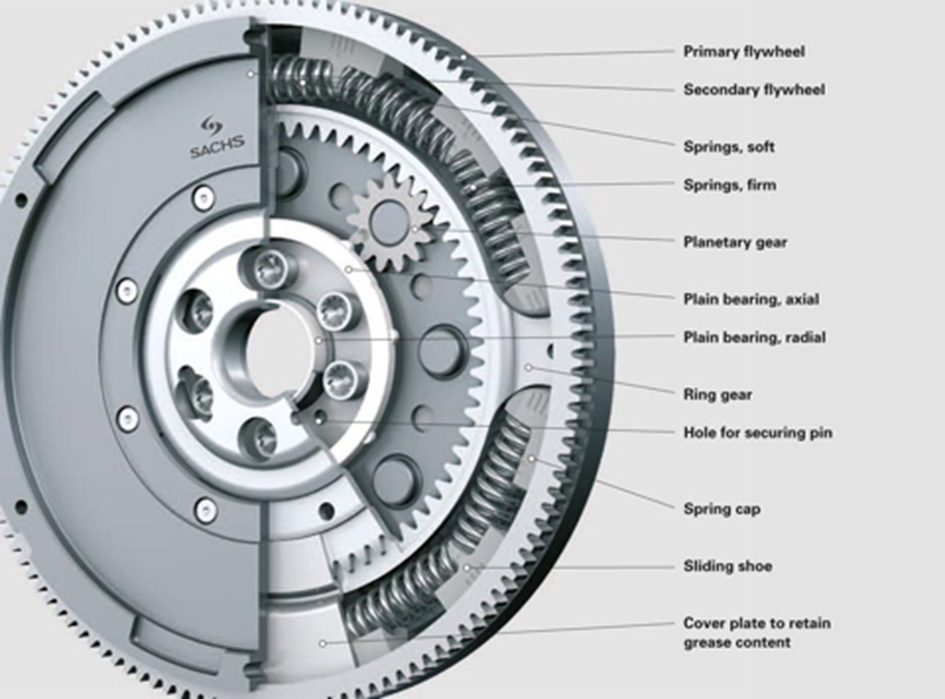

**Combustion Engines and Their Application to Vehicle - A.Y. 2018/2019**

**Team Number: 79**

**Team Members: Ragheed Huneineh (S265776)    ;   Aybek Guan (S267847)**

## **I. Introduction**

An engine flywheel is aimed to regularize the crankshaft speed. It does not affect the engine torque or power. It is designed on the base of the forces acting on the piston and the consequent momentum acting on the crankshaft. In the following sections you could see the calculation procedures, graphs, tables and results for given data.

### 1.1 Data To Be Calculated

This report consists in the calculation of:

- the thermodynamic state of the closed system composed by air, fuel and residuals in the key-points of the ideal air-fuel cycle

- the inertia pressure and effective pressure acting on the piston head and of the related forces acting on the piston head and on the connecting rod

- the shaft momentum and resistant momentum acting on the crankshaft in case of a single-cylinder engine

- the dynamic irregularity and the diameter of the designed flywheel, given a target kinematic irregularity, in case of a single-cylinder engine

- the instantaneous velocity of the crankshaft in case of a single-cylinder engine

- the total shaft momentum and resistant momentum acting on the crankshaft in a multi-cylinder engine, considering an evenly spaced phase shift

- the dynamic irregularity and the diameter of the designed flywheel, given a target kinematic irregularity, for the multi-cylinder engine  

Requirements:

- - in-cylinder pressure VS swept volume (indicated cycle on p-V chart) 

- - effective pressure as a function of the crank angle peff(θ) 

- - indicated cycle with inertia pressure (properly over-imposed) 

- - tangential tension as a function of the crank angle t(θ) 

- - shaft tension t(θ) and resistant tension tr(θ), shaft work (Ls/V) and resistant work (Lr/V) as a function of crank angle (all in one graph)

- - instantaneous velocity 

- Numerical results for pressure and temperature of points 1 to 4, lower heating value at temperature T2, dynamic irregularity and flywheel diameter for the single-cylinder as well as for the multi-cylinder engine; 

- Required charts (both for the single-cylinder engine and for the multi- cylinder engine):

- in-cylinder pressure VS swept volume (indicated cycle on p-V chart) 

- effective pressure as a function of the crank angle peff(θ) 

- indicated cycle with inertia pressure (properly over-imposed) 

- tangential tension as a function of the crank angle t(θ) 

- shaft tension t(θ) and resistant tension tr(θ), shaft work (Ls/V) and resistant work (Lr/V) as a function of crank angle (all in one graph)

- instantaneous velocity 

### 1.2 Hypothesis And Assumption

In this exercise the analysis will be conducted considering a single steady-state engine working point on a SI naturally aspirated engine with indirect injection (fuel and air induced together through the intake valve during the intake process).

Instead of a real indicated cycle, we will consider a simplified air-fuel cycle.

Hypothesis:

- Intake and exhaust valves are opened instantaneously at the dead centres

- Intake and exhaust phases occur at constant pressure

- Combustion and blow-down phases occur at constant volume

- Compression and expansion phases are described as polytrophic transformations

Considerations: 

- that variation of the chemical internal energy is null since no chemical reaction occurs during the process 

- the work done by the system through the control surface as the sum of the work done the by means of the displacement of the piston plus the (negative) work done by the external environment to “push” inside the cylinder the volume of air + fuel 

- the heat exchanged during the process as the heat needed to increase of 30° the temperature of the air + fuel + residuals mixture 

### 1.2 Given Data

% Clear ALL
clear all
close all
clc

% Engine Characteristic
ic = 6; % [-] number of cylinders
d = 72.5*1e-3; % [m] bore
c = 66*1e-3; % [m] stroke
epsilon = 9.4; % [-] compression ratio
lambda = 0.25; % [-] crank slider parameter
n = 5400; % [rpm] engine speed
AM = 1.2*1e3; % [kg/m^3] alternative masses
ERM = 0.85*1e3; % [kg/m^3] equivalent rotating masses

% Data for point 1 calculation
Pa = 100658; % [Pa] environment pressure
Ta = 297; % [K] environment temperature
lambdav = 0.82; % [-] volumetric efficiency
Pr_Pa = 1.15; % [-] residual to environment pressure ratio
Tr = 903; % [K] residual temperature
alpha_st = 14.7; % [-] stoichiometric air-to-fuel ratio
R_alpha = 0.95; % [-] relative air-to-fuel ratio
Cb = 2500; % [J/(Kg.K)] fuel specific heat
x = 1; % [-] fuel vaporized fraction
r = 320000; % [J/Kg] fuel vaporization heat
delta_T = 30; % [degC] temperature increment for the air-fuel-residual mixture during the intake stroke
R = 287.2; % [J/(Kg.K)] air elastic constant
Rp = 288; % [J/(Kg.K)] burnt gas elastic constant
R1 = 271; % [J/[Kg.K)] air-fuel-residual mixture elastic constant
Cp = 1009; % [J/(Kg.K)] air specific heat
Cpp = 1150; % [J/Kg.K)] burnt gas specific heat

% Data for point 2 calculation
m = 1.35; % [-] comression index
% To calculate lower heating value at T2
Cv = 744; % [J/(Kg.K)] air specific heat
Cvp = 824; % [J/(Kg.K)] burnt gas specific heat
Hiv_T0 = 44000000; % [J/Kg] lower heating value at T0 = 288 K
T0 = 288; % [K]

% Data for point 3 calculation
% Dissciation heat
dq = 0.54; % [J/(Kg.K^2)]
Td = 1850; % [K]
Cpp3 = 1328; % [J/(Kg.K)] burnt gas specific heat
delta_A = 0.06; % [-] heat loss coefficient

% Data for point 4 calculation
mp = 1.27; % [-] expansion index

% Data for flywheel design
Gamma_v = 7.7*1e3; % [Kg/m^3] density
delta = 0.01; %  [-] kinematic irregularity


## II. Methodology

### 2.1 Analysis of The Indicated Cycle

To begin with, we have calculated the values for both temperature (T) and pressure (P) in 4 points of our cycle. To calculate each value, we implied different approach wich are described below:

**P1:** From the exercises we did in class, we get that $m_1 =m_a +m_f +m_r$ and for the temperature and pressure we use:


$$T_1 =\frac{\left(\lambda c_p +c_f \right)T_a +\alpha^{\prime } {{c^{\prime } }_p T}_r -x_r }{\alpha c_p +c_f +\alpha^{\prime } {c^{\prime } }_p }+\Delta T$$



$$P_1 =p_a \left\lbrack \lambda_v \left(\frac{1+\alpha }{\alpha }\right)\left(\varepsilon -1\right)\frac{1}{RT_a }+\frac{p_r }{p_a }\frac{1}{RT_r }\right\rbrack \frac{R_1 T_1 }{\varepsilon }$$


where: $\alpha =\frac{m_a }{m_f }$ and $\alpha^{\prime } =\frac{m_r }{m_f }$ while **R** is the elastic air constant and **R'** is the burnt gas elastic constant.

% P1
Vd = pi*d^2*c/4; % [m^3] displacement volume
Vc = Vd/(epsilon-1); % [m^3] clearance volume
Vt = Vd + Vc; % [m^3] total cylinder volume
Pr = Pa*Pr_Pa; % [Pa] % residual gas pressure
alpha = alpha_st*(R_alpha); % [-] air-to-fuel ratio
alphap = Pr*Vc*R*Ta/Pa/Vt/Rp/Tr/lambdav; % [-] residual-to-fuel ratio

T1 = ((alpha*Cp + Cb)*Ta + alphap*Cpp*Tr - x*r)/(alpha*Cp + Cb + alphap*Cpp) + delta_T; % [K]
P1 = Pa*R*T1/epsilon*(lambdav*((1+alpha)/alpha)*(epsilon-1)/R/Ta + Pr/Pa/Rp/Tr); % [Pa]


**P2:** Assuming polytropic evolution (1 -> 2), we can get T2 and P2:


$$P_2 =P_1 {\left(\frac{V_1 }{V_2 }\right)}^m =P_1 \varepsilon^m$$



$$T_2 =T_1 {\left(\frac{V_1 }{V_2 }\right)}^{m-1} =T_1 \varepsilon^{m-1}$$


% P2
P2 = P1*epsilon^m; % [Pa]
T2 = T1*epsilon^(m-1); % [K]


**P3:** Application of the 1st law of thermodynamics in the LaGrange form (closed system) to the transformation in the figure below, we get:

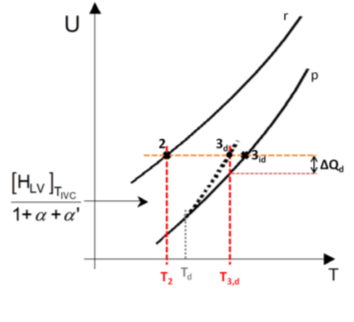


$$P_3 =P_2 \frac{R_3 }{R_2 }\frac{T_3 }{T_2 }=P_2 \frac{R^{\prime } }{R_1 }\frac{T_3 }{T_2 }$$


% P3
Hiv_T2 = Hiv_T0 + (1+alpha)*(Cv-Cvp)*(T2-T0); % [J/Kg]
A = dq;
B = Cvp-2*dq*Td;
C = dq*Td^2 - Cvp*T2 - (1-delta_A)*R_alpha*Hiv_T2/(1+alpha+alphap);
ROOTS = roots([A B C]);
T3 = ROOTS(ROOTS>T2); % [K]
P3 = P2*Rp*T3/R1/T2; % [Pa]


**P4:** We can consider here also another polytropic transformation; therefore we get:


$$P_4 =P_3 {\left(\frac{V_3 }{V_4 }\right)}^{m^{\prime } } =P_3 \varepsilon^{-m^{\prime } }$$



$$T_4 =T_3 {\left(\frac{V_3 }{V_4 }\right)}^{m^{\prime } -1} =T_3 \varepsilon^{1-m^{\prime } }$$


% P4
P4 = P3*epsilon^-mp; % [Pa]
T4 = T3*epsilon^(1-mp); % [K]

**P5:** Here, we can only say that the pressure is equal to that of the residual pressure.

% P5
P5 = Pr; % [Pa]


**P6:** Also here, the pressure is equal to that of the residual pressure.

% P6
P6 = Pr; % [Pa]


**P7:** In this case, the pressure is equal to that calculated in point 1.

% P7
P7 = P1; % [Pa]


After all main points are known, we could draw a PV diagram, which represents graphically the working cycle of our engine. To make it possible we should generate a generic vector of the crank angle representing a full engine cycle, from which we could calculate the position of the piston and hence, the volume of the cylinder.

$X_p =r_c \left\lbrack \left(1-\mathrm{cos}\left(\theta \right)\right)+\frac{1}{\lambda }\left(1-\sqrt{1-{\left(\lambda \mathrm{sin}\left(\theta \right)\right)}^2 }\right)\right\rbrack$ ; multiplied by the cylinder cross-sectional area we get the volume!

% Crank-slider mechanism
theta = [0:180 180:360 360:540 540:720]; % [deg]
c_r = c/2; % [m] crank radius
area = pi*d^2/4; % [m^2] cylinder cross-sectional area
x_p = c_r*((1-cosd(theta)) + 1/lambda*(1-sqrt(1-lambda^2*sind(theta).^2))) + Vc/area; % [m] piston position
V = area*x_p; % [m^3] cylinder volume vs theta

% Pressure vs Volume
% Expansion (3 -> 4)
V34 = V(1:181);
P(1:181) = P3*(Vc./V34).^mp;

% Blowdown (4 -> 5)
P(182) = P5;

% Exhaust (5 -> 6)
P(183:362) = P6;

% Intake (6 -> 7 -> 1)
P(363) = P7;
P(364:543) = P1;

% Compression (1 -> 2)
V12 = V(544:723);
P(544:723) = P1*(Vt./V12).^m;

% Combustion (2 -> 3)
P(724) = P3;

figure(1)
hold on
plot(V*1e6, P*1e-5, 'b')
title('Pressure vs. Volume')
xlabel('Volume [cm^3]')
ylabel('Pressure [bar]')
grid on

### 2.2 Calculation of "imep" And of The Crankshaft Momentum: Single-Cylinder Engine

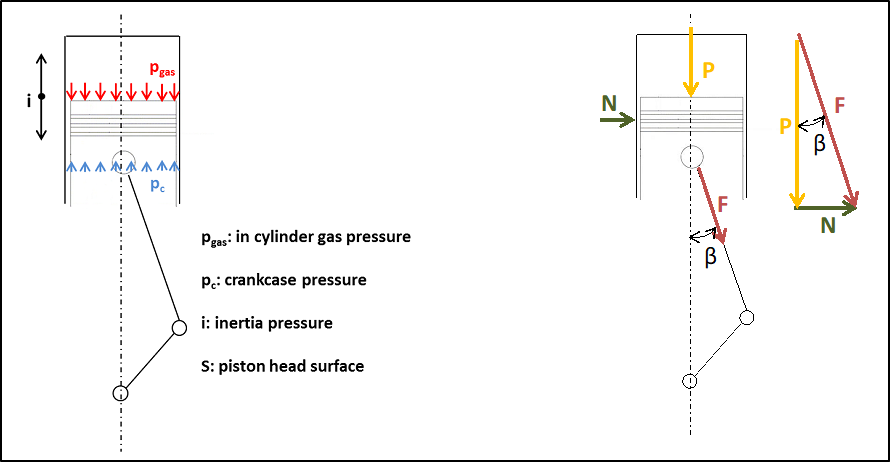

For calculating the inertia pressure, we found the value of inertia force and divided it by the known cylinder cross-section area. After the value is known, we put it onto the PV diagram for more comprehensive visualization:


$$F_{\mathrm{in}} =-m_{\mathrm{alt}} \omega^2 r_c \left(\mathrm{cos}\left(\theta \right)+\frac{\lambda \mathrm{cos}\left(2\theta \right)}{\mathrm{cos}\left(\beta \right)}\right)$$


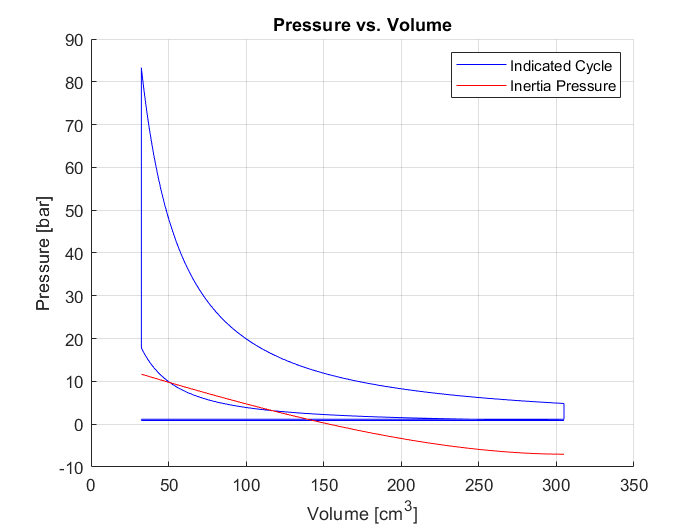

% Inertia Pressure
beta = asind(lambda*sind(theta)); % [deg]
omega = n*2*pi/60; % [rad/s]
Fin = -AM*Vt*omega^2*c_r*(cosd(theta) + lambda*cosd(2*theta)./cosd(beta)); % [N] Inertia Force
Pin = Fin/area; % [Pa] Inertia Pressure

plot(V*1e6, -Pin*1e-5, 'r')
legend('Indicated Cycle', 'Inertia Pressure')

Effective pressure can be calculated taking the data from previous points, since it's equal to:


$$P_{\mathrm{eff}} =P-P_a +P_{\mathrm{in}}$$


where **P** is the pressure inside the cylinder depending on the piston position, $P_a$ is the enviromental pressure, and $P_{\mathrm{in}}$ is the inertia pressure.

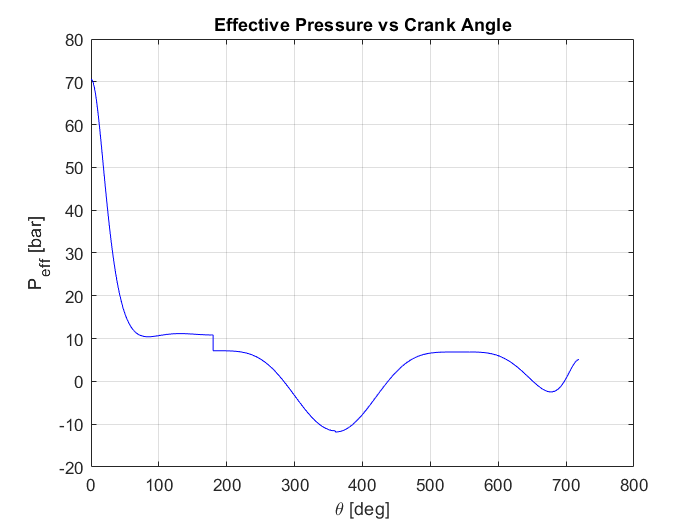

% Effective Pressure
Peff = P - Pa + Pin; % [Pa] effective pressure
figure(2)
plot(theta(1:end-1), Peff(1:end-1)*1e-5, 'b')
title('Effective Pressure vs Crank Angle')
xlabel('\theta [deg]')
ylabel('P_e_f_f [bar]')
grid on

The value of the tangential tension, $t\left(\theta \right)$, can be found using the shaft momentum, $M\left(\theta \right)$, and the displacement volume. The calculation path is the following:


$$F=p_{\mathrm{eff}} \frac{A}{\mathrm{cos}\left(\beta \right)}$$


however, the actual force is the tangential component, so we calculate the angle **'**$\gamma$**'** from geometry and applying trigonometric relations, we obtain:


$$F_t =F\;\mathrm{sin}\left(\gamma \right)$$


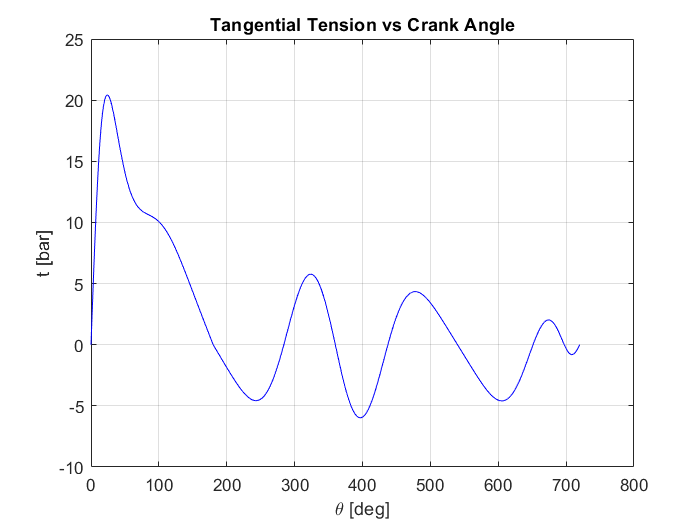

% Tangential Tension
gamma = theta + beta; % [deg]
F = Peff*area./cosd(beta); % [N] force along connecting rod
Ft = F.*sind(gamma); % [N] tangential force
Ms = Ft*c_r; % [Nm] shaft moment
t = Ms/(Vd/2); % [Pa] tangential tension
figure(3)
plot(theta, t*1e-5, 'b')
title('Tangential Tension vs Crank Angle')
xlabel('\theta [deg]')
ylabel('t [bar]')
grid on

To calculate the **imep**, the calculation requires the following integration:


$$\mathrm{imep}=\frac{\oint {\mathrm{dL}}_i }{V}=\frac{1}{V}\left(\int_1^2 \mathrm{pdV}+\int_3^4 \mathrm{pdV}+\int_5^6 \mathrm{pdV}+\int_7^1 \mathrm{pdV}\right)$$


where:


$$\frac{1}{V}\int_1^2 \mathrm{pdV}=\varepsilon p_1 \left(\frac{\varepsilon^{m-1} -1}{\left(\varepsilon -1\right)\left(1-m\right)}\right)$$



$$\frac{1}{V}\int_3^4 \mathrm{pdV}=p_3 \left(\frac{\varepsilon^{1-m^{\prime } } -1}{\left(\varepsilon -1\right)\left(1-m^{\prime } \right)}\right)$$



$$\frac{1}{V}\int_5^6 \mathrm{pdV}=-p_r$$



$$\frac{1}{V}\int_7^1 \mathrm{pdV}=p_1$$


At this point we can calculate the resistive moment and tension according to the following equations:

$M_r =\frac{{\mathrm{imepV}}_d }{4\pi }$          and          $t_r =\frac{M_r }{\frac{V_d }{2}}$

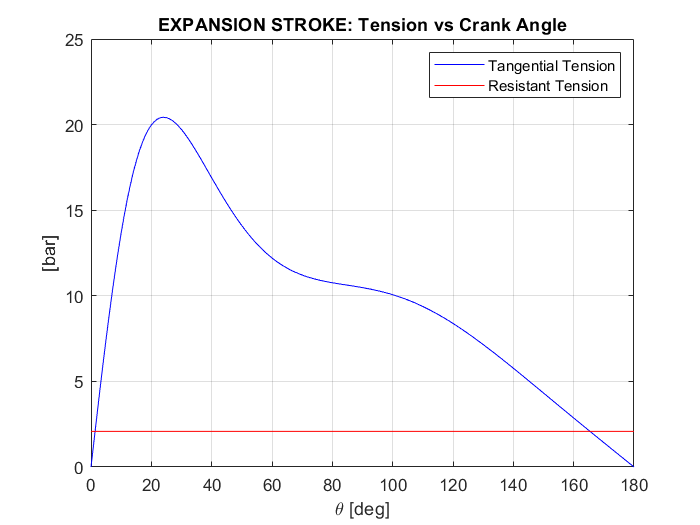

% Indicated Mean Effective Pressure
imep = P3*(epsilon^(1-mp)-1)/(epsilon-1)/(1-mp) + P1 - Pr + epsilon*P1*(epsilon^(m-1)-1)/(epsilon-1)/(1-m);

% Resistive Moment and Tension
Mr = imep*Vd/4/pi*ones(1, 724); % [Nm] resistive moment
tr = Mr/(Vd/2); % [Pa] resitive tension
figure(4)
plot(theta(1:181), t(1:181)*1e-5, 'b', theta(1:181), tr(1:181)*1e-5, 'r')
title('EXPANSION STROKE: Tension vs Crank Angle')
xlabel('\theta [deg]')
ylabel('[bar]')
legend('Tangential Tension', 'Resistant Tension')
grid on

### 2.3 Calculation of The Flywheel Diameter: Single-Cylinder Engine

Referring to the last figure, we realize that during the intake cycle the tangential tension is varying with respect to the crank angle while the resistant tension is constant. This is where the flywheel comes into play, saving the excess energy when the tangential tension is higher than the resistant tension and giving it back when its lower. To achieve its role, a thorough flywheel design procedure is followed by referring to the minimum rotational speed of the crankshaft ‘ωmin’ and the maximum rotational speed of the crankshaft $\omega_{\mathrm{max}}$ caused by the energy variation. These rotational speeds are calculated according to the following set of equations:


$$\omega_{\mathrm{avg}} =\frac{\omega_{\mathrm{max}} +\omega_{\mathrm{min}} }{2}$$
                                                    
$$\delta =\frac{\omega_{\mathrm{max}} -\omega_{\mathrm{min}} }{\omega_{\mathrm{avg}} }$$


Where **'**$\delta$**'** is the kinematic irregularity given with a value of **0.01**.

At this point, we must calculate the minimum and maximum energy given by the tangential tension and the resistant tension. This is achieved by applying numerical trapezoidal integration from the start of the stroke until the first intersection between the two curves for the minimum energy, and from the start of the stroke till the last intersection for the maximum energy. On MATLAB, a function called **InterX** allowed us to obtain the intersections between the two curves and then we were able to use the **trapz** function to calculate the corresponding integrals:


$$L_{s,\mathrm{min}} =\int_0^{\theta_{\mathrm{min}} } M_s \left(\theta \right)d\theta$$
                                      
$$L_{r,\mathrm{min}} =\int_0^{\theta_{\mathrm{min}} } M_r \left(\theta \right)d\theta$$



$$L_{s,\mathrm{max}} =\int_0^{\theta_{\mathrm{max}} } M_s \left(\theta \right)d\theta$$
                                      
$$L_{r,\mathrm{min}} =\int_0^{\theta_{\mathrm{max}} } M_r \left(\theta \right)d\theta$$
  

The calculation procedure proceeds by calculating the dynamic irregularity, **'**$\zeta$**'**, as follows:


$$\zeta =\frac{\Delta L_{\mathrm{max}} +\left|\Delta L_{\mathrm{min}} \right|}{\mathrm{imep}\;V}$$


where:


$$\Delta L_{\mathrm{max}} =L_{s,\mathrm{max}} -L_{r,\mathrm{max}}$$
                                   
$$\Delta L_{\mathrm{min}} =L_{s,\mathrm{min}} -L_{r,\mathrm{min}}$$


By using again numerical integration but in this case implementing it in a for-loop, we obtain the above figure representing the engine work and the resistant work as a function of the crank angle. Note that it’s essential for the two curves to intersect at the end of the cycle due to the principle of conservation of energy implied during the design of the flywheel.

From the dynamic irregularity, it’s possible to calculate the moment of inertia of the engine with the flywheel according to the following equation:

$J=\frac{\zeta \;\mathrm{imep}\;V}{\delta \;\omega_{\mathrm{avg}}^2 \;}$     given that: $J_{\mathrm{eng}} =\left(\frac{m_{\mathrm{rot}} }{\mathrm{iV}}\right)V\;r^2$

Then it’s possible to calculate the moment of inertia of the flywheel by subtracting that of the engine from the total moment of inertia. Given the density of the material from which the flywheel is made, the design of the flywheel is narrowed to the simple calculation of the diameter of the flywheel:

$J_{\mathrm{fly}} =\frac{\pi }{32}\rho w_{\mathrm{flywh}} D^4$     where it's assumed that: $w_{\mathrm{flywh}} =\frac{D}{10}$

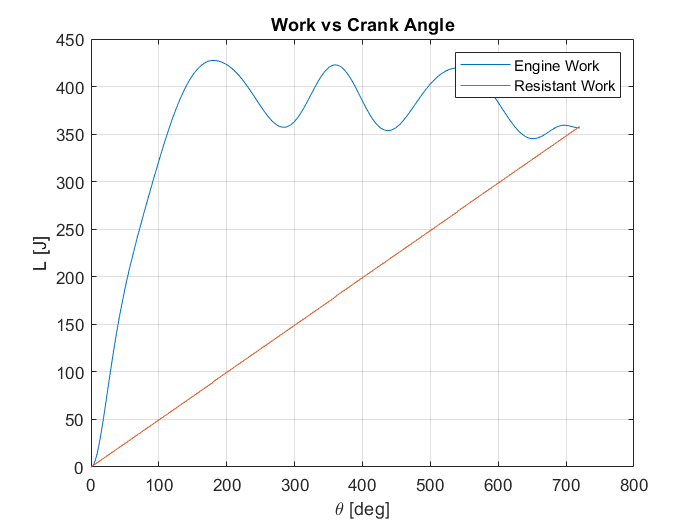

% Dynamic Irregularity
omega_max = omega*(2+delta)/2; % [rad/s] maximum angular velocity
omega_min = omega_max - delta*omega; % [rad/s] minimum angular velocity
THETAS = InterX([theta(1:181); t(1:181)], [theta(1:181); tr(1:181)]);
theta_min = THETAS(1, 1); % [deg] theta @ omega_min
theta_max = THETAS(1, 2); % [deg] theta @ omega_max
Ls_min = trapz(theta(theta<=theta_min)*pi/180, Ms(theta<=theta_min)); % [J] 
Lr_min = trapz(theta(theta<=theta_min)*pi/180, Mr(theta<=theta_min)); % [J]
deltaL_min = Ls_min - Lr_min; % [J]
Ls_max = trapz(theta(theta<=theta_max)*pi/180, Ms(theta<=theta_max)); % [J]
Lr_max = trapz(theta(theta<=theta_max)*pi/180, Mr(theta<=theta_max)); % [J]
deltaL_max = Ls_max - Lr_max; % [J]
deltaL_t = deltaL_max + abs(deltaL_min); % [J]
zeta = deltaL_t/imep/Vd; % [-] dynamic irregularity

% Flywheel
J = zeta*imep*Vd/delta/omega^2; % [kg.m^2] moment of inertia
J_eng = ERM*Vd*c_r^2; % [Kg.m^2] engine moment of inertia
J_fly = J - J_eng; % [Kg.m^2] flywheel moment of inertia
D = (J_fly*320/pi/Gamma_v)^(1/5); % [m] flywheel diameter

% Shaft Instantaneous Angular Velocity
Ls(1) = 0;
Lr(1) = 0;
for i = 2:length(theta)
    Ls(i) = trapz([theta(i-1) theta(i)]*pi/180, [Ms(i-1) Ms(i)])+Ls(i-1);
    Lr(i) = trapz([theta(1) theta(2)]*pi/180, [Mr(1) Mr(2)])+Lr(i-1);
end
figure(5)
plot(theta, Ls)
hold on
plot(theta, Lr)
title('Work vs Crank Angle')
xlabel('\theta [deg]')
ylabel('L [J]')
legend('Engine Work', 'Resistant Work')
grid on

### 2.4 Calculation of The Instantaneous Crankshaft Speed: Single-Cylinder Engine

Performing a double integration of Newton’s 2nd Law applied on the crankshaft throughout one cycle, it’s possible to obtain the instantaneous angular velocity of the crankshaft according to the following equation:


$$\omega \left(\theta \right)=\sqrt{\omega^2 +2\frac{L_s \left(\theta \right)-L_r \left(\theta \right)}{J}}$$


Due to the difference between the average values, the curve is shifted accordingly.

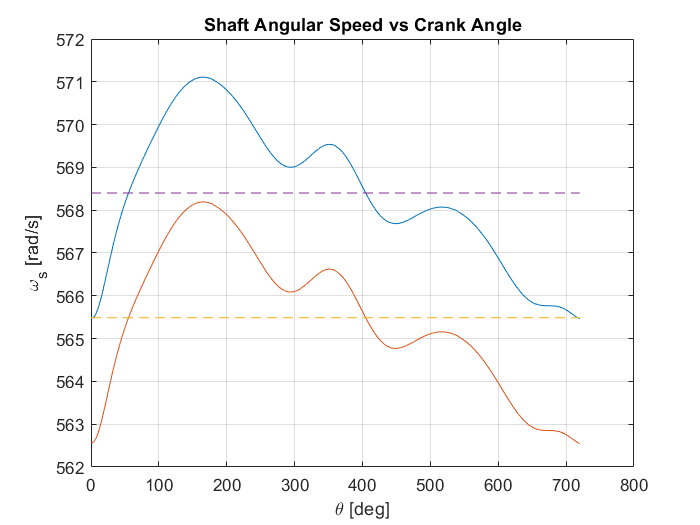

omega_i = sqrt(omega^2 + 2/J*(Ls-Lr));
shift = mean(omega_i) - omega;
omega_ii = omega_i - shift;

figure(6)
plot(theta, omega_i, theta, omega_ii, [0 720], [omega omega], '--', [0 720], [mean(omega_i) mean(omega_i)], '--')
title('Shaft Angular Speed vs Crank Angle')
xlabel('\theta [deg]')
ylabel('\omega_s [rad/s]')
grid on

### 2.5 Calculation of The Shaft And Resistant Momentum: Multi-Cylinder Engine

In this section, we illustrate the behavior of a 6-cylinder engine based on the calculations performed for a single-cylinder engine. This is achieved by shifting the calculated tangential tension for a single-cylinder engine by a phase shift taking into consideration the firing order of the cylinders. The typical firing order for a 6-cylinder engine is: 1-4-2-6-3-5. The phase shift is calculated as follows:

$\Delta \phi =\frac{m\;360}{i}$        where **m** is the number of rounds per cycle and **i** is the number of cylinders

The tangential tension of the engine is given by the summation of the tangential tensions of each cylinder throughout the cycle.

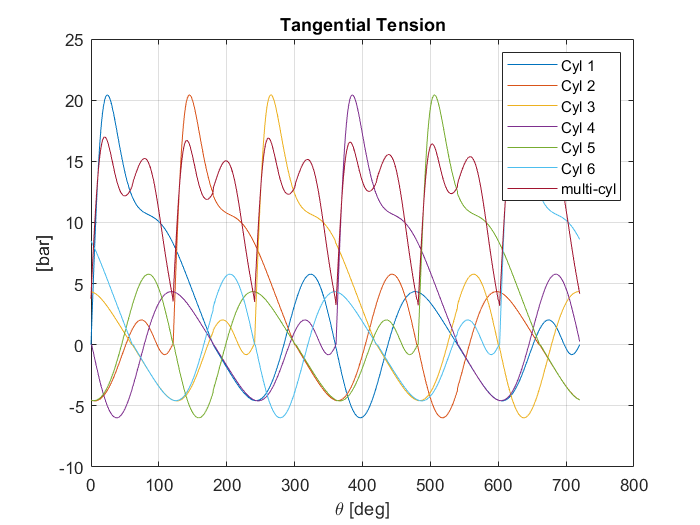

% Multi-cylinder Engine
delta_phi = 720/ic; % [deg] Phase Shift
% Cylinder: 1
Ms_c1 = Ms; % [Nm]
t_c1 = t; % [Pa]
Mr_c1 = Mr; % [Nm]
tr_c1 = Mr_c1/(Vd/2); % [Pa]

% Cylinder 2
Ms_c2(1:delta_phi+1) = Ms(end-delta_phi:end); % [Nm]
Ms_c2(delta_phi+2:724) = Ms(1:end-delta_phi-1); % [Nm]
t_c2(1:delta_phi+1) = t(end-delta_phi:end);% [Pa]
t_c2(delta_phi+2:724) = t(1:end-delta_phi-1); % [Pa]
Mr_c2(1:delta_phi+1) = Mr(end-delta_phi:end); % [Nm]
Mr_c2(delta_phi+2:724) = Mr(1:end-delta_phi-1); % [Nm]
tr_c2 = Mr_c2/(Vd/2); % [Pa]

% Cylinder 3
Ms_c3(1:2*(delta_phi+1)) = Ms(end-2*(delta_phi+1)+1:end); % [Nm]
Ms_c3(2*(delta_phi+1)+1:724) = Ms(1:end-2*(delta_phi+1)); % [Nm]
t_c3(1:2*(delta_phi+1)) = t(end-2*(delta_phi+1)+1:end);% [Pa]
t_c3(2*(delta_phi+1)+1:724) = t(1:end-2*(delta_phi+1)); % [Pa]
Mr_c3(1:2*(delta_phi+1)) = Mr(end-2*(delta_phi+1)+1:end); % [Nm]
Mr_c3(2*(delta_phi+1)+1:724) = Fin(1:end-2*(delta_phi+1)); % [Nm]
tr_c3 = Mr_c3/(Vd/2); % [Pa]

% Cylinder 4
Ms_c4(1:3*(delta_phi+1)) = Ms(end-3*(delta_phi+1)+1:end); % [Nm]
Ms_c4(3*(delta_phi+1)+1:724) = Ms(1:end-3*(delta_phi+1)); % [Nm]
t_c4(1:3*(delta_phi+1)) = t(end-3*(delta_phi+1)+1:end);% [Pa]
t_c4(3*(delta_phi+1)+1:724) = t(1:end-3*(delta_phi+1)); % [Pa]
Mr_c4(1:3*(delta_phi+1)) = Mr(end-3*(delta_phi+1)+1:end); % [Nm]
Mr_c4(3*(delta_phi+1)+1:724) = Mr(1:end-3*(delta_phi+1)); % [Nm]
tr_c4 = Mr_c4/(Vd/2); % [Pa]

% Cylinder 5
Ms_c5(1:4*(delta_phi+1)) = Ms(end-4*(delta_phi+1)+1:end); % [Nm]
Ms_c5(4*(delta_phi+1)+1:724) = Ms(1:end-4*(delta_phi+1)); % [Nm]
t_c5(1:4*(delta_phi+1)) = t(end-4*(delta_phi+1)+1:end);% [Pa]
t_c5(4*(delta_phi+1)+1:724) = t(1:end-4*(delta_phi+1)); % [deg]
Mr_c5(1:4*(delta_phi+1)) = Mr(end-4*(delta_phi+1)+1:end); % [Nm]
Mr_c5(4*(delta_phi+1)+1:724) = Mr(1:end-4*(delta_phi+1)); % [Nm]
tr_c5 = Mr_c5/(Vd/2); % [Pa]

% Cylinder 6
Ms_c6(1:5*(delta_phi+1)) = Ms(end-5*(delta_phi+1)+1:end); % [Nm]
Ms_c6(5*(delta_phi+1)+1:724) = Ms(1:end-5*(delta_phi+1)); % [Nm]
t_c6(1:5*(delta_phi+1)) = t(end-5*(delta_phi+1)+1:end);% [Pa]
t_c6(5*(delta_phi+1)+1:724) = t(1:end-5*(delta_phi+1)); % [Pa]
Mr_c6(1:5*(delta_phi+1)) = Mr(end-5*(delta_phi+1)+1:end); % [Nm]
Mr_c6(5*(delta_phi+1)+1:724) = Mr(1:end-5*(delta_phi+1)); % [Nm]
tr_c6 = Mr_c6/(Vd/2); % [Pa]

% Engine
Ms_eng = Ms_c1 + Ms_c2 + Ms_c3 + Ms_c4 + Ms_c5 + Ms_c6;
t_eng = Ms_eng/(Vd/2);
Mr_eng = imep*ic*Vd/4/pi*ones(1, 724);
tr_eng = Mr_eng/(Vd/2);
figure(7)
plot(theta, t_c1*1e-5, theta, t_c2*1e-5, theta, t_c3*1e-5,...
    theta, t_c4*1e-5, theta, t_c5*1e-5, theta, t_c6*1e-5,...
    theta, t_eng*1e-5)
title('Tangential Tension')
xlabel('\theta [deg]')
ylabel('[bar]')
grid on
legend('Cyl 1', 'Cyl 2', 'Cyl 3', 'Cyl 4', 'Cyl 5', 'Cyl 6', 'multi-cyl')

### 2.6 Calculation of The Flywheel Diameter: Multi-Cylinder Engine

As shown in the above figure, the tangential and resistant tensions are represented to visualize the intersections between the two curves and perform the same procedure for calculating the dynamic irregularity. Note that the result must satisfy the following condition:


$$\zeta_{\mathrm{multi}-\mathrm{cylinder}} =\frac{\zeta_{\mathrm{single}-\mathrm{cylinder}} }{i}$$


% Dynamic Irregularity
THETAS_eng = InterX([theta(1:121); t_eng(1:121)], [theta(1:121); tr_eng(1:121)]);
theta_min_eng = THETAS_eng(1, 1); % [deg]
theta_max_eng = THETAS_eng(1, end); % [deg]
Ls_min_eng = trapz(theta(theta<=theta_min_eng)*pi/180, Ms_eng(theta<=theta_min_eng)); % [J] 
Lr_min_eng = trapz(theta(theta<=theta_min_eng)*pi/180, Mr_eng(theta<=theta_min_eng)); % [J]
deltaL_min_eng = Ls_min_eng - Lr_min_eng; % [J]
Ls_max_eng = trapz(theta(theta<=theta_max_eng)*pi/180, Ms(theta<=theta_max_eng)); % [J]
Lr_max_eng = trapz(theta(theta<=theta_max_eng)*pi/180, Mr(theta<=theta_max_eng)); % [J]
deltaL_max_eng = Ls_max_eng - Lr_max_eng; % [J]
deltaL_t_eng = deltaL_max_eng + abs(deltaL_min_eng); % [J]
zeta_eng = deltaL_t_eng/imep/Vd/ic; % [-] dynamic irregularity

% Engine Flywheel
J1 = zeta_eng*imep*Vd/delta/omega^2; % [kg.m^2] moment of inertia
J_eng1 = ERM*Vd*ic*c_r^2; % [Kg.m^2] engine moment of inertia
J_fly_eng = J1 - J_eng1; % [Kg.m^2] flywheel moment of inertia
D1 = (J_fly_eng*320/pi/Gamma_v)^(1/5); % [m] flywheel diameter

### 2.7 Calculation of The Instantaneous Crankshaft Speed: Multi-Cyilnder Engine

The following steps follow the exact same procedure done for the single-cylinder engine to calculate the instantaneous crankshaft velocity represented in the following figure.

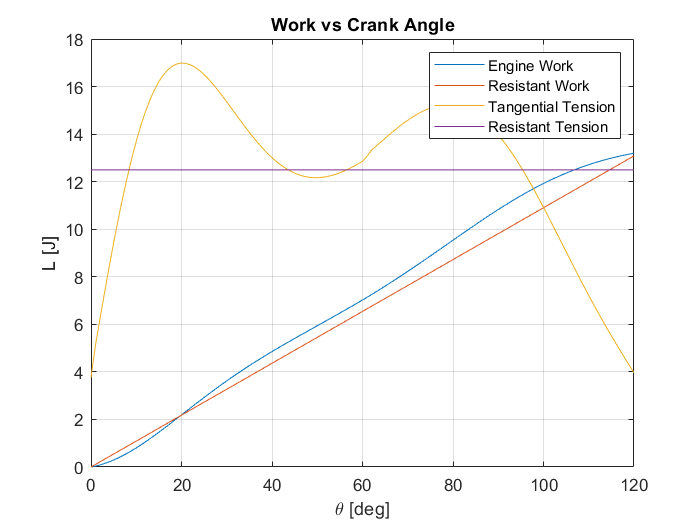

% Work
Ls_eng(1) = 0;
Lr_eng(1) = 0;
for i = 2:length(theta)
    Ls_eng(i) = trapz([theta(i-1) theta(i)]*pi/180, [Ms_eng(i-1) Ms_eng(i)])+Ls_eng(i-1);
    Lr_eng(i) = trapz([theta(i-1) theta(i)]*pi/180, [Mr_eng(i-1) Mr_eng(i)])+Lr_eng(i-1);
end
figure(8)
plot(theta(1:121), Ls_eng(1:121)/Vd*1e-5)
hold on
plot(theta(1:121), Lr_eng(1:121)/Vd*1e-5)
plot(theta(1:121), t_eng(1:121)*1e-5)
plot(theta(1:121), tr_eng(1:121)*1e-5)
title('Work vs Crank Angle')
xlabel('\theta [deg]')
ylabel('L [J]')
legend('Engine Work', 'Resistant Work', 'Tangential Tension', 'Resistant Tension')
grid on

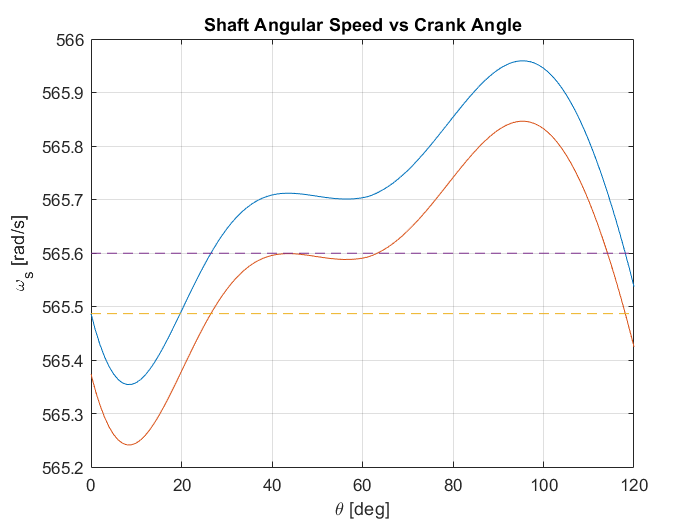


omega_i_eng = sqrt(omega^2 + 2/J*(Ls_eng-Lr_eng));
shift_eng = mean(omega_i_eng) - omega;
omega_ii_eng = omega_i_eng - shift_eng;

figure(9)
plot(theta(1:121), omega_i_eng(1:121), theta(1:121), omega_ii_eng(1:121), ...
    [0 120], [omega omega], '--', [0 120], [mean(omega_i_eng) mean(omega_i_eng)], '--')
title('Shaft Angular Speed vs Crank Angle')
xlabel('\theta [deg]')
ylabel('\omega_s [rad/s]')
grid on

## III. Numerical Results

fprintf(1, ['Key Point \t Temperature [K] \t Pressure [bar] \n 1 \t\t %g \t\t %g \n' ...
    ' 2 \t\t %g \t\t %g \n 3 \t\t %g \t\t %g \n 4 \t\t %g \t\t %g'], T1, P1, T2, P2, T3, P3, T4, P4)

Key Point 	 Temperature [K] 	 Pressure [bar] 
 1 		 309.826 		 86667.3 
 2 		 678.754 		 1.78475e+06 
 3 		 2981.69 		 8.33203e+06 
 4 		 1628.24 		 484037

fprintf(['Lower Heating Value: \t %g \n' ...
    'Dynamic Irregularity Single Cylinder: \t %g\n' ...
    'Flywheel Diameter Single Cylinder: \t %g\n' ...
    'Dynamic Irregularity Multi-Cylinder: \t %g\n' ...
    'Flywheel Diameter Multi-Cylinder: \t %g'], Hiv_T2, zeta, D, zeta_eng, D1)

Lower Heating Value: 	 4.35322e+07 
Dynamic Irregularity Single Cylinder: 	 0.959973
Flywheel Diameter Single Cylinder: 	 0.269153
Dynamic Irregularity Multi-Cylinder: 	 0.126574
Flywheel Diameter Multi-Cylinder: 	 0.175537